# Àlgrebra lineal - Resolució de Sistemes

A = [1,2,1;-2,7,3;1,-1,10];

%DETERMINANT
det(A)

%NORMA
norm(A,1) %per columnes
norm(A,'inf') % per files
norm(A,2) % max(sqrt(eig(A*A')))

%INVERSA
B=inv(A)

%VALORS I VECTORS PROPIS
[V,D]=eig(A), inv(V)*A*V

## Diverses Matrius

%Mat de 0
zeros(3)

%Mat Id
eye(3)

%Mat 1
ones(3)

%RNG se li pot posar randi(limit,tamany)
rand(3), randi(2,3) 

%Mat de hilbert
hilb(4), invhilb(4)

%Magic
M=magic(5)

M=magic(5)

%Diag agafa sa diagonal o crea una matriu amb sa diagonal que toca
R= diag(diag(M))

v=[1 2 3 4 5]; diag(v)

%triangular inferior, també se li poden posar parametres
tril(M)
tril(M,-1)

%triangular superior triu, se li poden posar parametre ometre n fila
%despres de diagonal



Factorització A=L*U

Factoritzció Arit A=R' * R

Factorització QR qr(A)= [Q,R], R-> Triangular Sup, Q-> ortogonal | QRx=b | Q(Rx) =b | Rx = Q'b

## Exemple

n=20;
A= zeros(n);
b= zeros(n,1);
for j= 1:n
    for i= 1:n
        aux=0;
        if(i == j) 
            aux=-1;
        elseif i < j
            aux=max(i,j);
        end
        A(i,j)=aux;
    end
    b(j)= 2^-j;
end

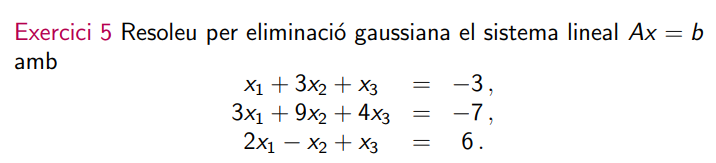

A= [1 3 1; 3 9 4; 2 -1 1];
b= [-3 -7 6]';

res= A\b % Resol sistemes d'eq
[L,U,P]=lu(A) % Retona triangular superior, inferior i ses permutacions

% 1) forward 

u= L\(P*b)

% 2) Ux=u

v= U\u

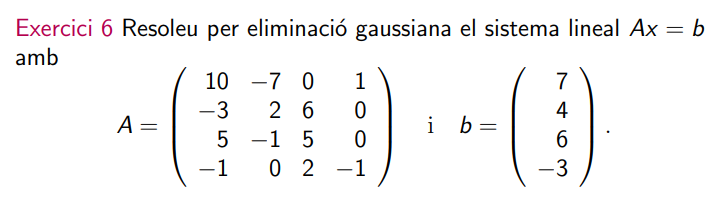

A= [10 -7 0 1;-3 2 6 0; 5 -1 5 0; -1 0 2 -1]; 
b=[7 4 6 -3]';

res= A\b
cond(A)

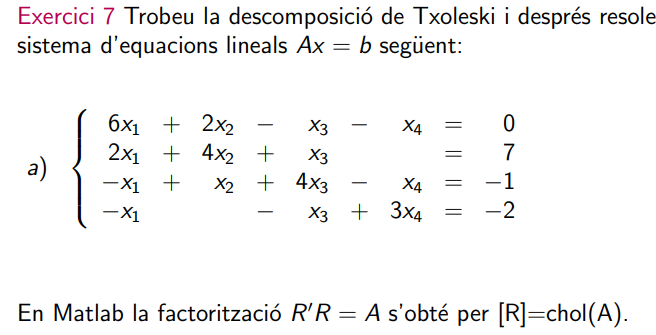

A= [6 2 -1 -1; 2 4 1 0; -1 1 4 -1; -1 0 -1 3];
b= [0 7 -1 -2]';

isequal(A,A')

R=chol(A)

R'*R

%1) R'y=b

y=R'\b

%2) Rx=y

x= R\y

% Mateix resultat
A\b


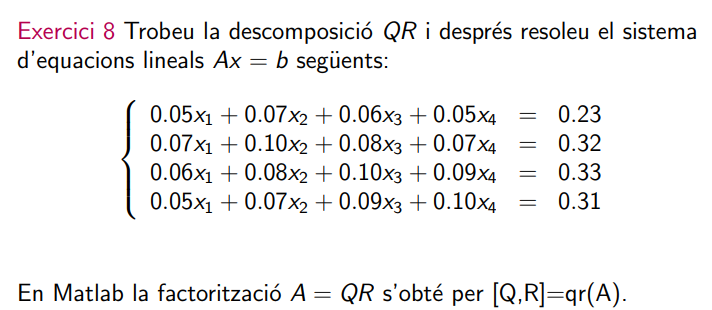

format short g
A= [5 7 6 5; 7 10 8 7; 6 8 10 9; 5 7 9 10]/100;
b=[23 32 33 31]'/100;

x= A\b

[q,r] = qr(A)


%1) rx=q'b

x= r\(q'*b)

## Vector residu

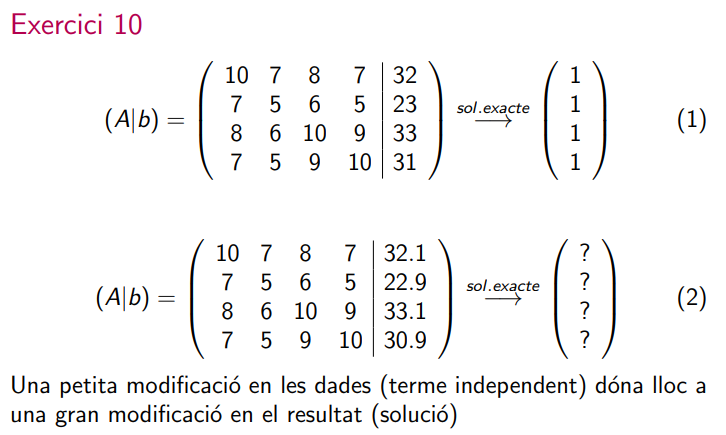

A=[10 7 8 7; 7 5 6 5; 8 6 10 9; 7 5 9 10];
b=[32 23 33 31]';
bb=[32.1 22.9 33.1 30.9]';

x=A\b, y=A\bb

r= norm(A*y-b,1) %error
db= norm(b-bb,1)

cond(A), rcond(A),det(A) % Si # de cond alt implica que sa mat no es molt estable en canvi rcond implica si esta ben condicionada
%factor propagacio error